# Electricity Revenue and Inflation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

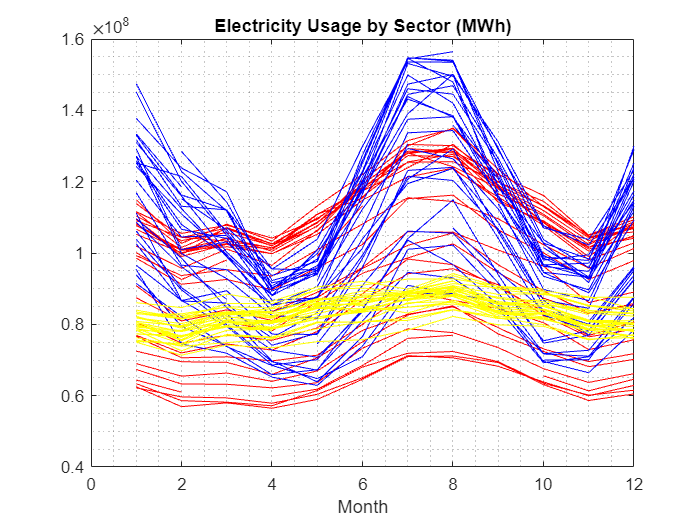

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');
price = readmatrix("./data/electricity.xlsx", Sheet='price');

plot(com, "r")
hold on
grid minor
plot(res, "b")
plot(ind, "y")
hold off
title("Electricity Usage by Sector (MWh)")
xlabel("Month")

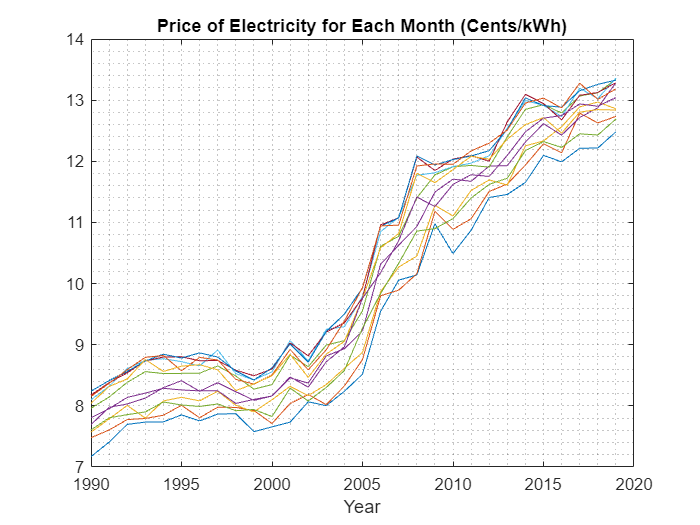

plot(1990:2019, price')
grid minor;
title("Price of Electricity for Each Month (Cents/kWh)")
xlabel("Year")

## Task 1

The first step is to combine data from the three sectors into an array containing the total usage.

Array addition and subtraction work element-wise; the operation is applied to each of the corresponding elements.

usage = com + res + ind;

## Task 2

To calculate revenue and inflation, the data need to be in compatible units. You will convert `price` to $/MWh to make it compatible with `usage` and the inflation rate, which is measured in dollars. To do this, you multiply the prices by 1000 kWh/MWh, and divide them by 100 ¢/$.

When performing arithmetic between an array and a scalar, each element in the array is operated on by the scalar.

price = price * 1000 / 100;